# Objective function calculations

In the following we do some calculations of the objective function and compare their outcomes and deduce some further steps.

First we import the precalculated embedding solutions

addpath("functions")
load materials\building.mat emb1 emb2

The embeddings are of the size **nx2**. *(see building.mlx)*

head(full(emb1))

ans =   -0.00045061   -0.0015351
   -0.0004468   -0.0026185
  -0.00025582   -0.0010982
  -0.00020003  -0.00039853
   -0.0004909   -0.0026878


head(full(emb2))

ans =    0.00012423   -0.0017225
   -1.933e-05   -0.0028075
   0.00017208   -0.0013608
   0.00026779  -0.00063745
  -6.7185e-05   -0.0031692


## Non-normalized objective function

We want to see which embedding does the goal of being minimal better, e.g. which procedure of computation *(see building.mlx)* is provably the sounder one. For this we look at the difference of their objective values (**ov**) we get from inserting the respective embedding into the objective function.

ov1 = ObjF(emb1);
ov2 = ObjF(emb2);
ov1 - ov2

ans =     -0.029995


Apparently, the second **ov** is a little bit better than the first in respect to minimizing. As it was calculated by means of the method matlab does encourage, namely the **A\b **call, we use this command for further calculations of embeddings instead of the call of **inv()**. For now we take the second embedding for subsequent calculations.

emb = emb2;

Let's now test the objective function on some aspects. For this we use **fplot()**. The usage as an example is as follows:

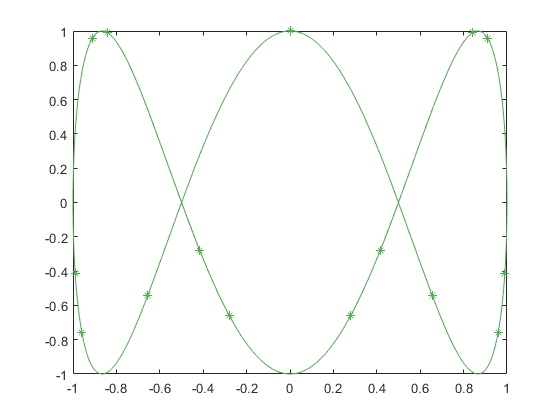

fp = fplot((@(x) sin(x)),(@(x) cos(3*x)));
fp.Color = "#5a5";
fp.Marker = "*";

To now plot our **ObjF()** we will need to select a specific interval. From testing we choose it as follows and plot the function in this interval.

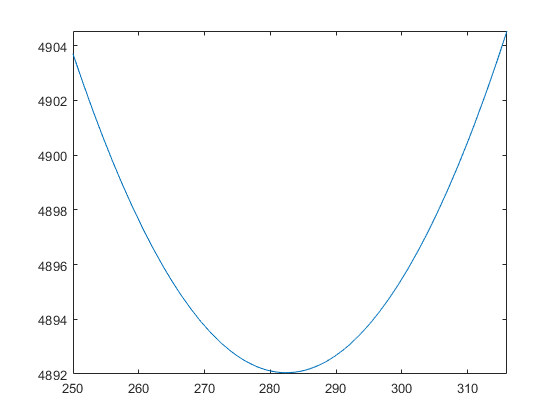

interval = [250 316];
fplot(@(x) ObjF(x*emb),interval);

We notice that the **ov** gets minimal for a scaling factor of around **283**. From this we can conclude that the unscaled embedding is not optimal. As to why this is the case we do have still work to do.

## Normalized objective function

While the non-normalized OF does give varying, but still unexpected **ov's**, the normalized OF on the other hand returns regardless of scaling of the embedding the same **ov's**. This is no surprise as the concept of normalization is exactly this disconnection from scaling.

ov1 = ObjFN(emb1);
ov2 = ObjFN(emb1*100);
ov1 - ov2

ans =     1.819e-12
